s=tf('s');
Wp=[(0.57*s+0.95)/(2*s+0.024) 0 0 0 0;...
     0 0.9 0 0 0;...
     0 0 0.15 0 0;
     0 0 0 (0.242*s+0.22)/(s+1) 0;...
     0 0 0 0 (1.08*s+1.8)/(4*s+0.048)];
Wu=(6*s+0.04)/(0.24*s+1)*eye(2);
Wn=[0.5*s+1 0;0 s+2]/(0.001*s+1);
int1=1/(s+10^-6);


G=ss(A,B,eye(4),0);
Wp = Wp(1:4, 1:4);
systemnames  = 'G Wp Wu int1';
inputvar     = '[r{4}; u{2}]';
outputvar    = '[Wp; r(1:2)-G(1:2); r(3:4)-G(3:4); int1]';
input_to_G   = '[u]';
input_to_int1 ='[r(1)-G(1)]';
input_to_Wp  = '[r-G]';
input_to_Wu  = '[u]';
% input_to_Wn =  '[n]';

P = minreal(sysic);

2 states removed.



G=ss(A,B,eye(4),0);
systemnames  = 'G  int1';
inputvar     = '[r{4}; u{2}]';
outputvar    = '[G;u; r(1:2)-G(1:2); r(3:4)-G(3:4); int1]';
input_to_G   = '[u]';
input_to_int1 ='[r(1)-G(1)]';
% input_to_Wp  = '[r-G; int1]';
% input_to_Wu  = '[u]';
% input_to_Wn =  '[n]';

Psim = minreal(sysic);

k4 = 2.8141;
k3 = 1.0995;
k2 = 34.1896;
k1 = 0.8351;
ki = 0.4473;
Kp = -[k1 k2 k3 k4 ki;k1 k2 k3 k4 ki]

Kp =    -0.8351  -34.1896   -1.0995   -2.8141   -0.4473
   -0.8351  -34.1896   -1.0995   -2.8141   -0.4473


w = logspace(-2,3,100);
Proba = lft(P,Kp)

Proba =

  Uncertain continuous-time state-space model with 4 outputs, 4 inputs, 7 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "Proba.NominalValue" to see the nominal value, "get(Proba)" to see all properties, and "Proba.Uncertainty" to interact with the uncertain elements.




isstable(Proba.NominalValue)

ans = logical
   1


kritmin = 1e6;
K = Kp;
Kmin = K;
for k1i = linspace(0.5*k1,1.5*k1,4)   
  for k2i = linspace(0.5*k2,1.5*k2,4) 
    for k3i = linspace(0.5*k3,1.5*k3,4)
      for k4i = linspace(0.5*k4,1.5*k4,4)
        for kii = linspace(0.5*ki,1.5*ki,4)
            
            K = -[k1i k2i k3i k4i kii;k1i k2i k3i k4i kii];
            Proba = lft(P.NominalValue,K);
            sig = sigma(Proba,w);
            krit= max(sig(1,:));
            if(krit < kritmin && isstable(Proba)) 
                Kmin = K;
                disp(krit)
                kritmin = krit;
            end
        end 
      end
    end
  end  
end

   37.2160

   31.2516

   21.6560

   16.2750

   15.4297

   13.8791

   12.8286

   12.1502



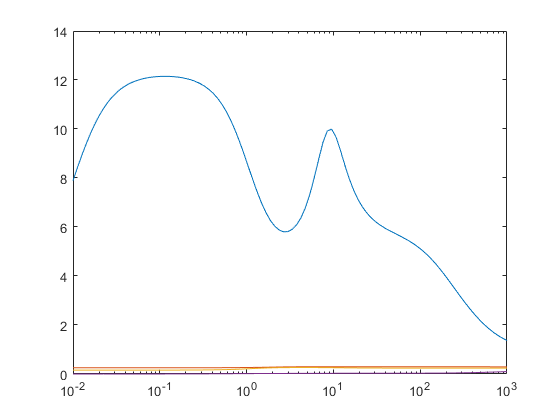


Proba = lft(P.NominalValue,Kmin);
sig = sigma(Proba,w);
figure;
semilogx(w,sig)

Gmu = lft(P,Kmin)

Gmu =

  Uncertain continuous-time state-space model with 4 outputs, 4 inputs, 7 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "Gmu.NominalValue" to see the nominal value, "get(Gmu)" to see all properties, and "Gmu.Uncertainty" to interact with the uncertain elements.




[Nmu, Del] = lftdata(Gmu);

Nrsmu = tf(Nmu);

Nrsmu = Nrsmu(1:2,1:2);

bndrsmu = mussv(frd(Nrsmu,w),[-1 0; -1 0]);

Points completed: 100/100


Points completed: 100/100


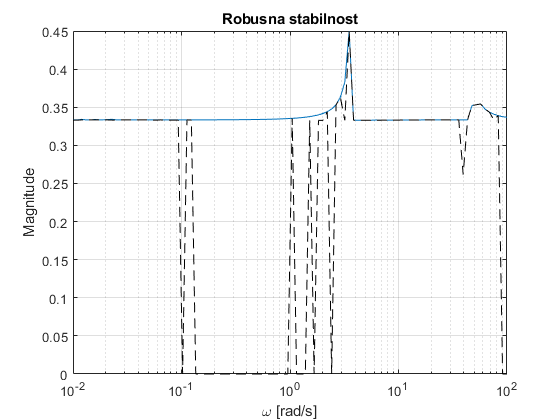

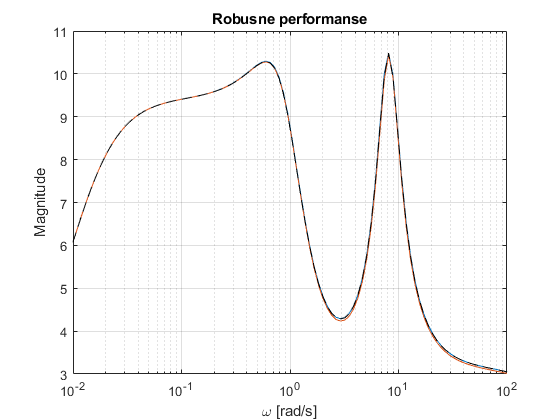



blkstr = [-1 0; -1 0; 4 4];
bndmu = mussv(frd(Nmu,w),blkstr);

  options = optimoptions('fminunc','Algorithm','quasi-newton','MaxFunctionEvaluations',100, ...
                         'ObjectiveLimit',0.8,'MaxIterations',10,'Display','iter');

par = [-1 -10 -1 -2 -0.5];
  [X,murp] = fminunc(@krit_fja, par, options, P.NominalValue, w);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           6          22.2233                          43.7
     1          18          15.6171     0.00228861           19.2  
     2          24          13.0181              1           16.8  
     3          36          12.3528            0.1           9.39  
     4          42          12.0645              1           20.8  
     5          48          11.7635              1           7.49  
     6         102          11.4864       0.330928           11.3  

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+02.



  
  Kopt = [X;X];

Kp = [par; par];
PsimCL = lft(Psim,Kp);
PsimCL2 = lft(Psim,Kmin);
PsimCL3 = lft(Psim,Kopt);
r = zeros(4,500);
r(1,:) = 1;
t = linspace(0,10,500);

[y1,t] = lsim(PsimCL.NominalValue, r, t);
[y2,t] = lsim(PsimCL2.NominalValue, r, t);
[y3,t] = lsim(PsimCL3.NominalValue, r, t);

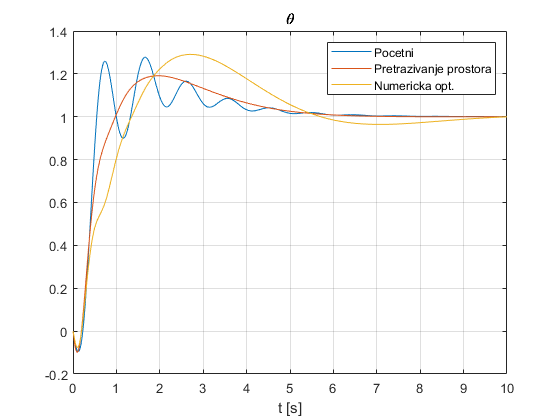


figure;
plot(t,y1(:,1),t,y2(:,1),t,y3(:,1))
legend('Pocetni', 'Pretrazivanje prostora', 'Numericka opt.')
xlabel('t [s]')
title('\theta')
grid on
print('fixStepth','-depsc')

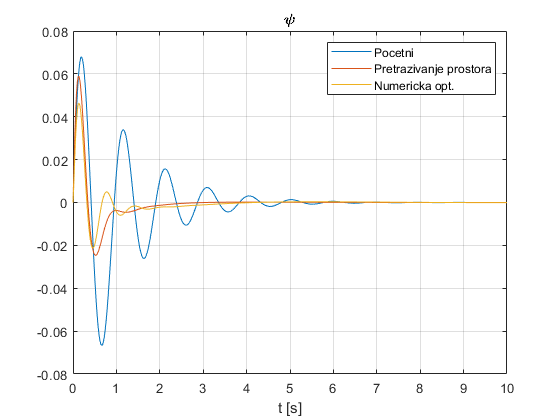


figure;
plot(t,y1(:,2),t,y2(:,2),t,y3(:,2))
legend('Pocetni', 'Pretrazivanje prostora', 'Numericka opt.')
xlabel('t [s]')
title('\psi')
grid on
print('fixSteppsi','-depsc')

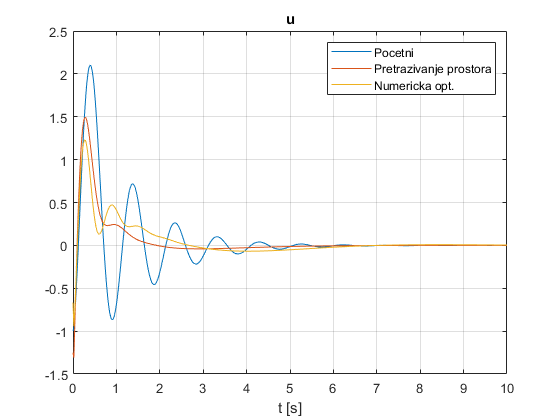


figure;
plot(t,y1(:,5),t,y2(:,5),t,y3(:,5))
legend('Pocetni', 'Pretrazivanje prostora', 'Numericka opt.')
xlabel('t [s]')
title('u')
grid on
print('fixStepu','-depsc')

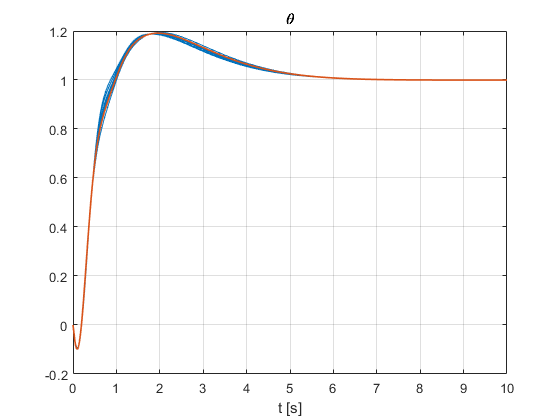

PsimCL2 = lft(Psim,Kmin);

uns1 = figure;
plot(t,y2(:,1), "Color",'#D95319', "LineWidth",1.2)
hold on
xlabel('t [s]')
title('\theta')
grid on

uns2 = figure;
plot(t,y2(:,2), "Color",'#D95319',"LineWidth",1.2)
hold on
xlabel('t [s]')
title('\psi')
grid on

uns3 = figure;
plot(t,y2(:,5), "Color",'#D95319',"LineWidth",1.2)
hold on
xlabel('t [s]')
title('u')
grid on


for i = 1:10
    [y2uns,t] = lsim(usample(PsimCL2), r, t);
    figure(uns1)
    plot(t,y2uns(:,1), "Color",'#0072BD', 'LineStyle',"-")
    
    figure(uns2)
    plot(t,y2uns(:,2), "Color",'#0072BD', 'LineStyle',"-")
    
    figure(uns3)
    plot(t,y2uns(:,5), "Color",'#0072BD', 'LineStyle',"-")
end

figure(uns1)
plot(t,y2(:,1), "Color",'#D95319', "LineWidth",1.2)
print('fixStepthUNS','-depsc')

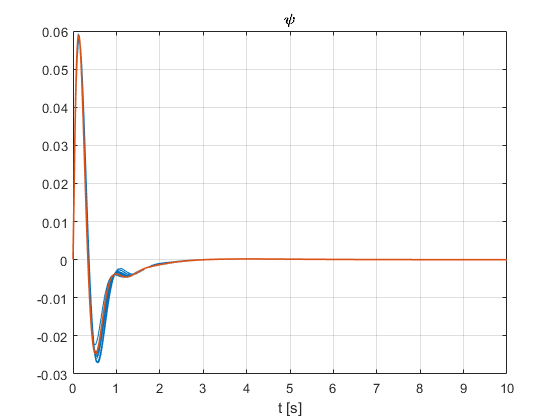


figure(uns2)
plot(t,y2(:,2), "Color",'#D95319',"LineWidth",1.2)
print('fixSteppsiUNS','-depsc')

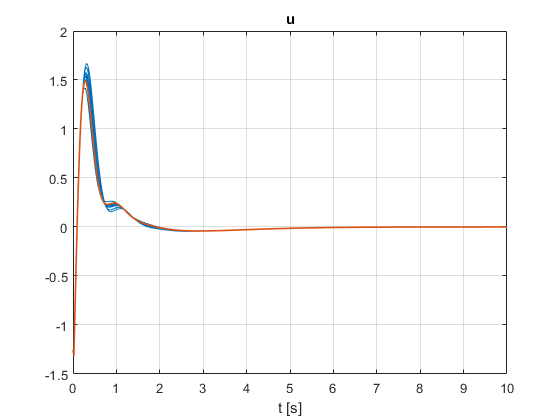


figure(uns3)
plot(t,y2(:,5), "Color",'#D95319',"LineWidth",1.2)
print('fixStepuUNS','-depsc')

N1 = lft(P,Kp);
N2 = lft(P,Kmin);
N3 = lft(P,Kopt);

[N1, Del] = lftdata(N1);
[N2, Del] = lftdata(N2);
[N3, Del] = lftdata(N3);

Nrs1= tf(N1);
Nrs1 = Nrs1(1:2,1:2);

Nrs2= tf(N2);
Nrs2 = Nrs2(1:2,1:2);

Nrs3= tf(N3);
Nrs3 = Nrs3(1:2,1:2);

bndrs1 = mussv(frd(Nrs1,w),[-1 0; -1 0]);

Points completed: 100/100


bndrs2 = mussv(frd(Nrs2,w),[-1 0; -1 0]);

Points completed: 100/100


bndrs3 = mussv(frd(Nrs3,w),[-1 0; -1 0]);

Points completed: 100/100



blkstr = [-1 0; -1 0; 4 4];

bndmu1 = mussv(frd(N1,w),blkstr);

Points completed: 100/100


bndmu2 = mussv(frd(N2,w),blkstr);

Points completed: 100/100


bndmu3 = mussv(frd(N3,w),blkstr);

Points completed: 100/100


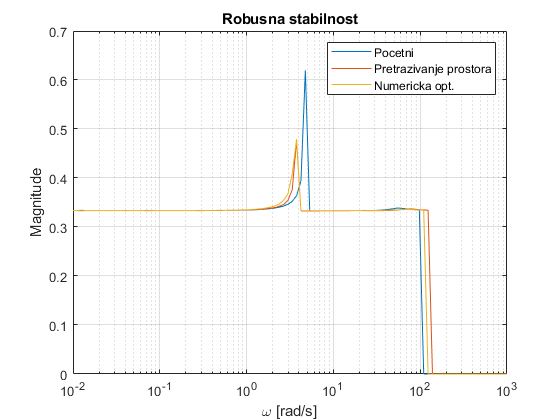


figure;
semilogx(w, squeeze(bndrs1.ResponseData(1,1,:)))
hold on
semilogx(w, squeeze(bndrs2.ResponseData(1,1,:)))
semilogx(w, squeeze(bndrs3.ResponseData(1,1,:)))
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusna stabilnost")
grid on
legend('Pocetni', 'Pretrazivanje prostora', 'Numericka opt.')
% print('fixRS','-depsc')

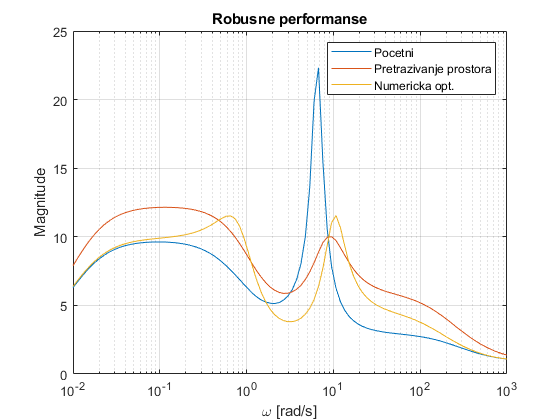


figure;
semilogx(w, squeeze(bndmu1.ResponseData(1,1,:)))
hold on
semilogx(w, squeeze(bndmu2.ResponseData(1,1,:)))
semilogx(w, squeeze(bndmu3.ResponseData(1,1,:)))
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusne performanse")
grid on
legend('Pocetni', 'Pretrazivanje prostora', 'Numericka opt.')
% print('fixRP','-depsc')